# Automatización del Análisis de Datos Solares

Una vez que hemos creado iterativamente nuestro análisis, es útil automatizarlo en forma de una función para poder realizar análisis similares en una variedad de ubicaciones y comparar los resultados.

## Seleccionar una Carpeta de Datos

Para seleccionar una carpeta de forma interactiva, descomenta la primera línea y comenta la segunda línea.

%folderName = uigetdir();
folderName = fullfile(pwd,'SolarData');
allFileNames = dir(fullfile(folderName,'*Daily.xlsx'));

## Ejecutar Análisis en Todos los Archivos Excel en la Carpeta

#### Preasignando variables

coeffs = zeros(length(allFileNames),4);
stationName = cell(length(allFileNames),1);

tic

#### Recorriendo todos los archivos Excel

BennettValleyDaily.xlsx


     General model:
     model(RelHum,delT) = a*(1+b*RelHum)*(1-exp(-c*delT^n))
     Coefficients (with 95% confidence bounds):
       a =      0.8645  (0.8408, 0.8881)
       b =   -0.003233  (-0.003597, -0.002869)
       c =    0.003574  (0.002362, 0.004785)
       n =       1.987  (1.866, 2.108)
91.899 percent of data points were within estimated bounds


BishopDaily.xlsx


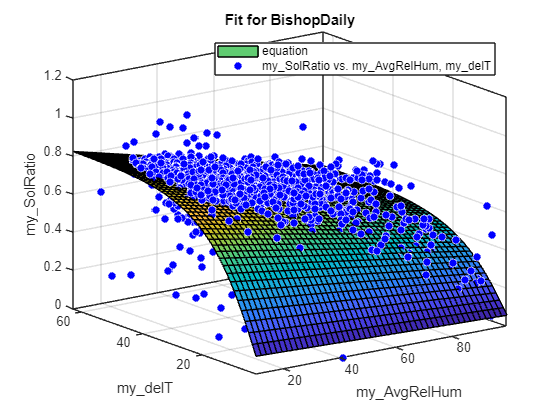

     General model:
     model(RelHum,delT) = a*(1+b*RelHum)*(1-exp(-c*delT^n))
     Coefficients (with 95% confidence bounds):
       a =      0.8593  (0.8442, 0.8744)
       b =   -0.004283  (-0.004615, -0.003951)
       c =     0.04474  (0.0254, 0.06408)
       n =       1.185  (1.036, 1.335)
95.616 percent of data points were within estimated bounds


BrentwoodDaily.xlsx


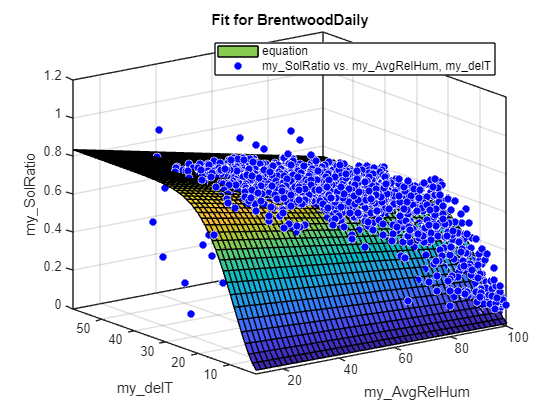

     General model:
     model(RelHum,delT) = a*(1+b*RelHum)*(1-exp(-c*delT^n))
     Coefficients (with 95% confidence bounds):
       a =      0.8621  (0.8452, 0.8789)
       b =   -0.003723  (-0.004003, -0.003444)
       c =    0.009274  (0.006215, 0.01233)
       n =       1.817  (1.692, 1.941)
91.061 percent of data points were within estimated bounds


CaminoDaily.xlsx


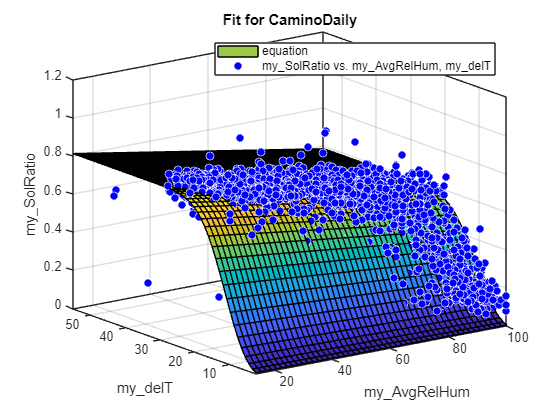

     General model:
     model(RelHum,delT) = a*(1+b*RelHum)*(1-exp(-c*delT^n))
     Coefficients (with 95% confidence bounds):
       a =      0.8432  (0.83, 0.8565)
       b =   -0.003087  (-0.003415, -0.002759)
       c =    0.001433  (0.0008851, 0.001981)
       n =        2.52  (2.372, 2.669)
90.934 percent of data points were within estimated bounds


DavisDaily.xlsx


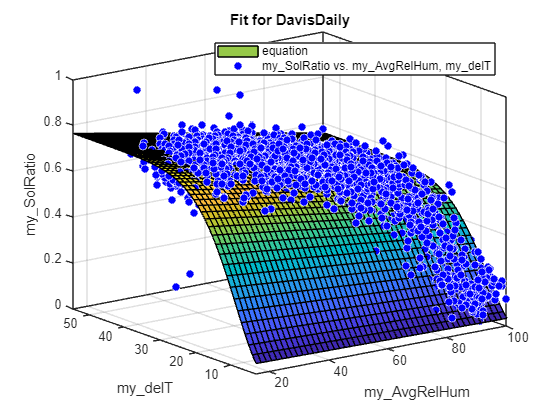

     General model:
     model(RelHum,delT) = a*(1+b*RelHum)*(1-exp(-c*delT^n))
     Coefficients (with 95% confidence bounds):
       a =      0.7995  (0.786, 0.8129)
       b =   -0.003053  (-0.003328, -0.002777)
       c =     0.01015  (0.007715, 0.01258)
       n =       1.757  (1.666, 1.847)
94.751 percent of data points were within estimated bounds


OxnardDaily.xlsx


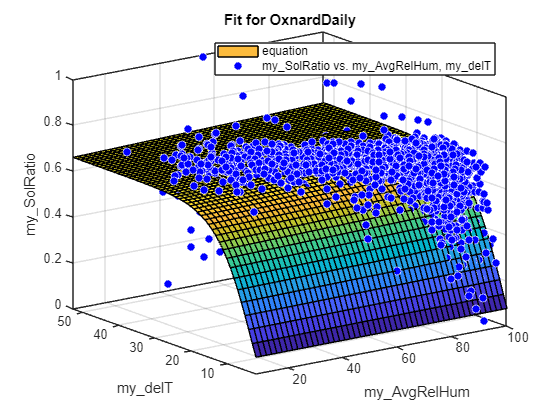

     General model:
     model(RelHum,delT) = a*(1+b*RelHum)*(1-exp(-c*delT^n))
     Coefficients (with 95% confidence bounds):
       a =      0.6555  (0.632, 0.6789)
       b =   0.0004727  (-0.0001582, 0.001104)
       c =     0.04839  (0.0345, 0.06228)
       n =       1.389  (1.251, 1.526)
98.072 percent of data points were within estimated bounds


PomonaDaily.xlsx


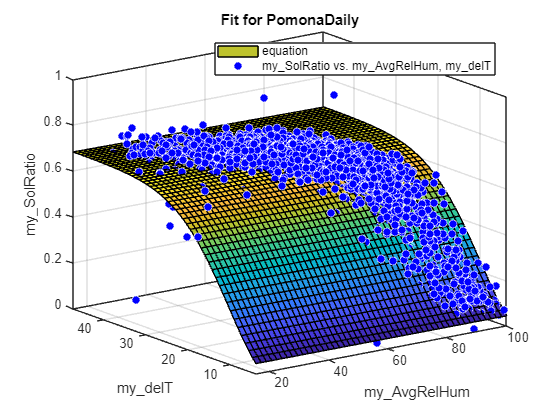

     General model:
     model(RelHum,delT) = a*(1+b*RelHum)*(1-exp(-c*delT^n))
     Coefficients (with 95% confidence bounds):
       a =      0.6846  (0.6684, 0.7008)
       b =  -0.0002374  (-0.0006956, 0.0002208)
       c =    0.006656  (0.005085, 0.008226)
       n =       1.825  (1.734, 1.916)
92.978 percent of data points were within estimated bounds


SantaBarbaraDaily.xlsx


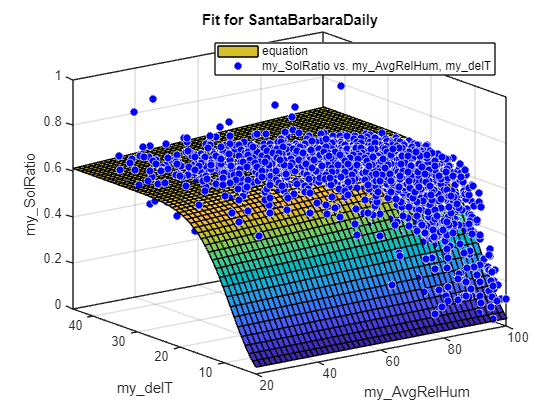

     General model:
     model(RelHum,delT) = a*(1+b*RelHum)*(1-exp(-c*delT^n))
     Coefficients (with 95% confidence bounds):
       a =      0.5953  (0.575, 0.6155)
       b =    0.001223  (0.0006194, 0.001827)
       c =    0.006518  (0.004575, 0.008461)
       n =       2.048  (1.924, 2.172)
94.633 percent of data points were within estimated bounds


SantaRosaDaily.xlsx


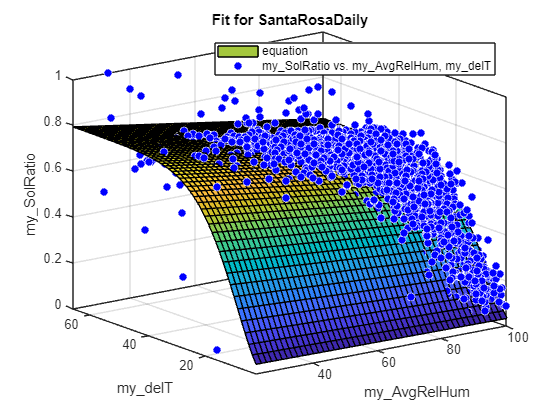

     General model:
     model(RelHum,delT) = a*(1+b*RelHum)*(1-exp(-c*delT^n))
     Coefficients (with 95% confidence bounds):
       a =      0.8403  (0.8152, 0.8654)
       b =   -0.002655  (-0.003035, -0.002275)
       c =     0.01107  (0.008435, 0.0137)
       n =       1.619  (1.53, 1.709)
93.956 percent of data points were within estimated bounds


UCRiversideDaily.xlsx


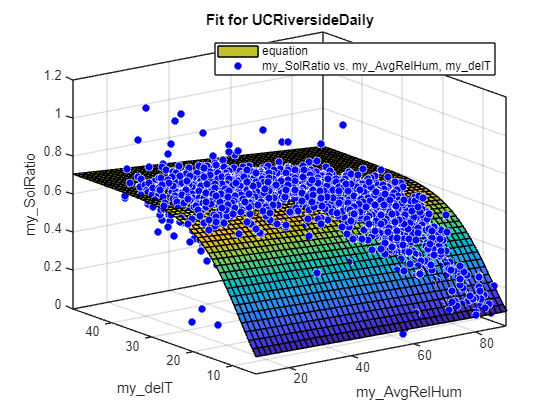

     General model:
     model(RelHum,delT) = a*(1+b*RelHum)*(1-exp(-c*delT^n))
     Coefficients (with 95% confidence bounds):
       a =       0.714  (0.7029, 0.7252)
       b =   -0.001846  (-0.002172, -0.001521)
       c =     0.01078  (0.007636, 0.01392)
       n =       1.776  (1.663, 1.89)
95.604 percent of data points were within estimated bounds


WindsorDaily.xlsx


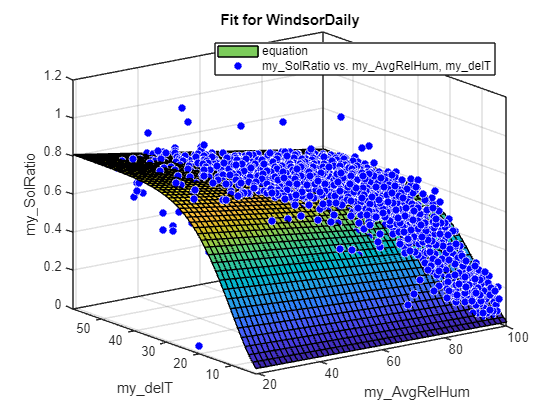

     General model:
     model(RelHum,delT) = a*(1+b*RelHum)*(1-exp(-c*delT^n))
     Coefficients (with 95% confidence bounds):
       a =      0.8566  (0.836, 0.8771)
       b =   -0.003213  (-0.003523, -0.002904)
       c =    0.007859  (0.005887, 0.009831)
       n =       1.736  (1.645, 1.828)
93.629 percent of data points were within estimated bounds


for ii = 1:length(allFileNames)
   
    % Display file processing
    disp(allFileNames(ii).name)
    
    % Create full file name and extract name of station
    fileName = fullfile(folderName,allFileNames(ii).name);
    [~, stationName{ii,1}, ~] = fileparts(allFileNames(ii).name);
    
    % Run Analysis Function
    [DayOfYear_test,EstRad,PredInt,SolRatio_test,model] = SolarAnalysisFcn(fileName);


    % Extract Coefficents
    coeffs(ii,:) = coeffvalues(model);
    
end

toc

Elapsed time is 27.640203 seconds.


## Write Results to an Excel File

VarNames = {'Station','a','b','c','n'};
T = table(stationName,coeffs(:,1),coeffs(:,2),coeffs(:,3),coeffs(:,4),'VariableName',VarNames);
writetable(T,'SolarFitResults.xlsx')

*Copyright 2024 The MathWorks, Inc.*